**Expected Result**

% Analytical Solution
syms x y;
f = x*y*exp(-(x^2 + y^2));

% Gradient of f(x,y)
grad_f = gradient(f, [x y]);

[x_sol, y_sol] = solve(grad_f(1) == 0, grad_f(2) == 0, x, y);

min = [];
max = [];
saddle = [];

% Hessian Matrix of f(x,y)
H = ((4*y*x^2 - 6*x*y)*(exp(-(x^2+y^2))))*((4*x*y^3 - 6*x*y)*(exp(-(x^2+y^2)))) - ((1 - 2*y^2 + 4*x^2*y^2 - 2*x^2)*(exp(-(x^2+y^2))))^2;
fxx = ((4*y*x^2 - 6*x*y)*(exp(-(x^2+y^2))));

% Determing type of extrema
cnt = [1,1,1];
for i = 1:length(x_sol)
    H_val = subs(H, [x, y], [x_sol(i), y_sol(i)]);
    if H_val < 0
        saddle(cnt(1), 1) = x_sol(i);
        saddle(cnt(1), 2) = y_sol(i);
        cnt(1) = cnt(1) + 1;
    elseif H_val > 0
        fxx_val = subs(fxx, [x, y], [x_sol(i), y_sol(i)]);
        if fxx_val < 0
            max(cnt(2), 1) = x_sol(i);
            max(cnt(2), 2) = y_sol(i);
            cnt(2) = cnt(2) + 1;
        elseif fxx_val > 0
            min(cnt(3), 1) = x_sol(i);
            min(cnt(3), 2) = y_sol(i);
            cnt(3) = cnt(3) + 1;
        end
    end
end

disp("Calculated Extrema:");

Calculated Extrema:


disp("Max:");

Max:


disp(max);

   -0.7071   -0.7071
    0.7071    0.7071



disp("Min:");

Min:


disp(min);

    0.7071   -0.7071
   -0.7071    0.7071



disp("Saddle:");

Saddle:


disp(saddle);

     0     0



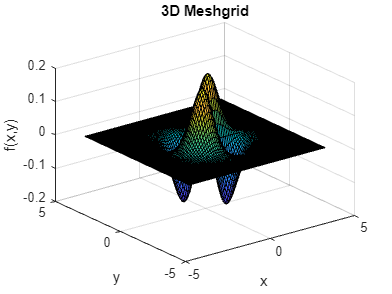


% Visualizing the graph
x = -4:0.1:4;
y = -4:0.1:4;

[X, Y] = meshgrid(x, y);
Z = X.*Y.*exp(-(X.^2 + Y.^2));

figure
surf(X, Y, Z)
xlabel('x')
ylabel('y')
zlabel('f(x,y)')
title('3D Meshgrid')

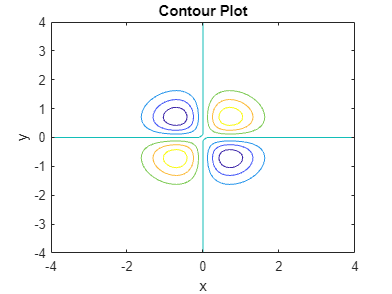


figure 
contour(X, Y, Z)
xlabel('x')
ylabel('y')
title('Contour Plot')

**Newton's Method**

NM_Step = 1; % Step size
NM_Extrema = [];
NM_Extrema(1,1:3) = NewtonMethod([-0.9, 0.9], NM_Step);
NM_Extrema(2,1:3) = NewtonMethod([0.9, -0.9], NM_Step);
NM_Extrema(3,1:3) = NewtonMethod([-0.9, -0.9], NM_Step);
NM_Extrema(4,1:3) = NewtonMethod([0.9, 0.9], NM_Step);
T = array2table(NM_Extrema,'VariableNames',{'X','Y','N'},'RowNames',{'Min1','Min2','Max1','Max2'});
disp("NM_Extrema");

NM_Extrema


disp(T);

               X           Y        N
            ________    ________    _

    Min1    -0.70711     0.70711    4
    Min2     0.70711    -0.70711    4
    Max1    -0.70711    -0.70711    4
    Max2     0.70711     0.70711    4



**Gradient Descent**

GD_Step = 1; % Step size
GD_Extrema = [];
GD_Extrema(1,1:3) = GradientDescent([0, 1], GD_Step);
GD_Extrema(2,1:3) = GradientDescent([0, -1], GD_Step);
T = array2table(GD_Extrema,'VariableNames',{'X','Y','N'},'RowNames',{'Max1','Max2'});
disp("GD_Extrema");

GD_Extrema


disp(T);

               X           Y        N
            ________    ________    _

    Max1    -0.70707     0.70721    8
    Max2     0.70707    -0.70721    8



Comparing the step size and number of iterations required

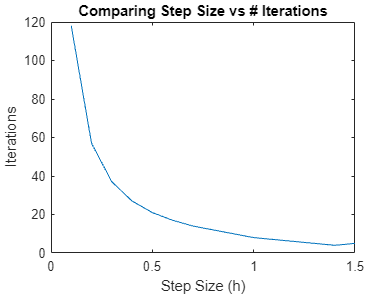

Itter = [];
cnt = 1;
for i = 0.1:0.1:1.5
    temp = GradientDescent([0, 1], i);
    Itter(cnt, 1) = i;
    Itter(cnt, 2) = temp(3);
    cnt = cnt + 1;
end
figure;
plot(Itter(:,1), Itter(:,2));
title("Comparing Step Size vs # Iterations");
xlabel("Step Size (h)");
ylabel("Iterations");